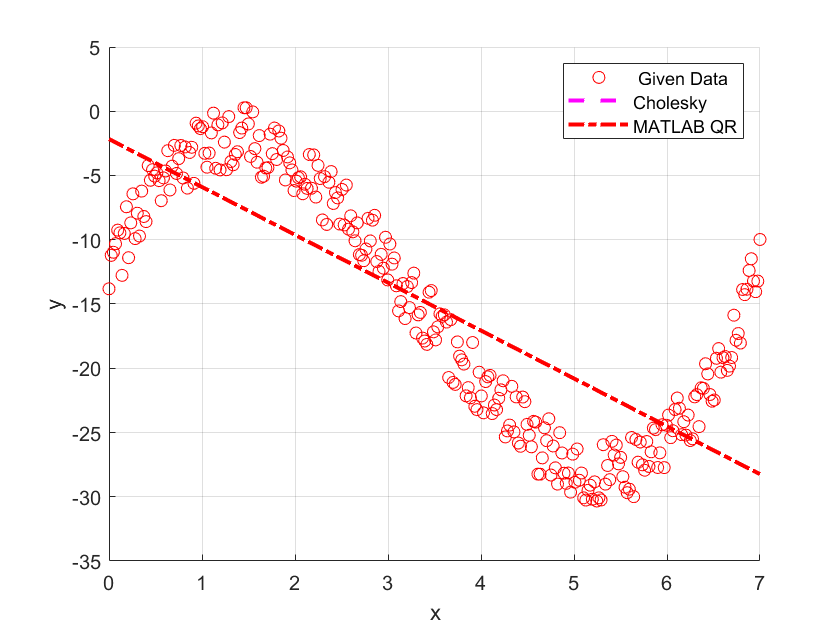

% Load the Input Data from the provided .mat file 

load('Polynomial_Fitting_Data.mat');

% set the degree
deg = 1;
% Define powers 
powers = 0:deg;
x = x_given;
y = y_given;

% get Polynomial Matrix 
Mp = PolynomialMatrix(x,deg);


   
   % MATLAB QR Decomposition
   [Q,R] = qr(Mp);
   
   % Find the polynomial coefficients using Q & R matrices obtained obove.
   
   % Name the Coefficeints obtained Cholesky  Ac
        % Use the MATLAB's Forward Slash Algorithm to obtain Ac 
        % by solving the normal equations (like we did in Tutorial)
            % Normal Eqautions: (Mp'*Mp)*Ac = Mp'*y
            % write your code here
   Ac = (Mp'*Mp)\(Mp'*y);
   % Name the Coefficeints obtained QR as Ar
       
            % write your code here
   Ar = R\Q'*y;
   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
   x_new = 0:0.01:7;
   x_new = x_new';
   
   fr = zeros(length(x_new),1);
   fc = zeros(length(x_new),1);
   
  
   for I = 1:length(powers)
       fr = fr + Ar(I)*x_new.^powers(I);   
       fc = fc + Ac(I)*x_new.^powers(I);
   end
   %plots
   figure(1)
   hold on
   plot(x,y,'ro')
   plot(x_new,fc,'m--','Linewidth',2)
   plot(x_new,fr,'r-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   legend(' Given Data','Cholesky','MATLAB QR')
   grid on

function M = PolynomialMatrix(x,n)
% write your code here
 % n is the degree of the polynomila
 % x is the vector of input data
 powers = 0:n;
 for i = 1:length(powers)
     M(:,i) = x.^powers(i);
 end
end